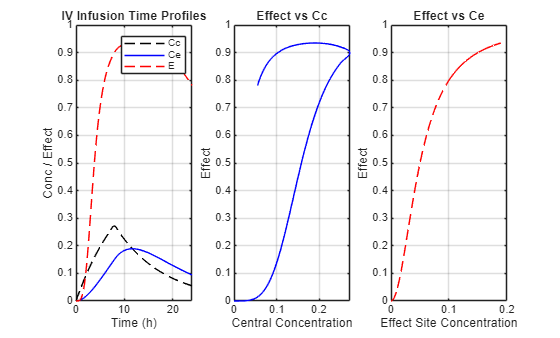

clear
clc


% PK PARAMETERS

CL  = 10;      % Clearance (L/h)
V   = 100;     % Volume (L)
ke0 = 0.2;     % Effect-site rate constant (1/h)

% Infusion settings
R0  = 5;       % Infusion rate (mg/h)
Tinf = 8;      % Infusion duration (h)



Emax = 1;
EC50 = 0.05;
n    = 2;

% TIME

t = 0:0.1:24;
tspan = [0 24];


% INITIAL CONDITIONS

% [Central Amount, Effect Site]
Initial = [0 0];

THETA = [CL V ke0 R0 Tinf];


% SOLVE ODE

sol = ode45(@IV_inf_PKPD, tspan, Initial, [], THETA);

Csol = deval(sol,t);

Ac = Csol(1,:);
Ce = Csol(2,:);

Cc = Ac ./ V;


% EFFECT

E = (Emax .* Ce.^n) ./ (EC50.^n + Ce.^n);


% PLOTS

figure
set(gcf,'Color','w')

subplot(1,3,1)
plot(t,Cc,'--k')
hold on
plot(t,Ce,'b')
plot(t,E,'--r')
xlabel('Time (h)')
ylabel('Conc / Effect')
title('IV Infusion Time Profiles')
legend('Cc','Ce','E')
grid on
hold off

subplot(1,3,2)
plot(Cc,E,'b-')
xlabel('Central Concentration')
ylabel('Effect')
title('Effect vs Cc')
grid on

subplot(1,3,3)
plot(Ce,E,'--r')
xlabel('Effect Site Concentration')
ylabel('Effect')
title('Effect vs Ce')
grid on